format long
trials = 10; % Number of trials
N = 10000; % Matrix size
QR_times = zeros(trials,1); % Array of timing data for the QR factorization trials
QR_errors = zeros(trials, 1);

GE_times = zeros(trials,1); % Array of timing data for the GE factorization trials
GE_errors = zeros(trials, 1);

for i=1:trials
    
    % Form a random matrix A and right-hand side b (normally distributed)
    A = randn(N,N);
    x = ones(N,1);
    
    b = A*x;

    % Apply backslash and calculate time taken for QR factorization
    tic;    
    [Q,R] = qr(A); % Compute the QR factorization of A      
    xhatQR = R\(Q.'*b);  % Solve the linear system (note that Q' is the transpose of Q)
    QR_times(i) = toc;       
    
    errors = xhatQR - x;
    QR_errors(i) = max(errors);
    
    % Apply backslash and calculate time taken for GE factorization
    tic;    
    xhatGE = A\b; % Solve the linear system using GE with partial pivoting    
    GE_times(i) = toc;  
    
    errors = xhatGE - x;
    GE_errors(i) = max(errors);
    
end

QR_mean_time = mean(QR_times)

QR_mean_time =   29.004360687776671


GE_mean_time = mean(GE_times)

GE_mean_time =    9.413187476777150


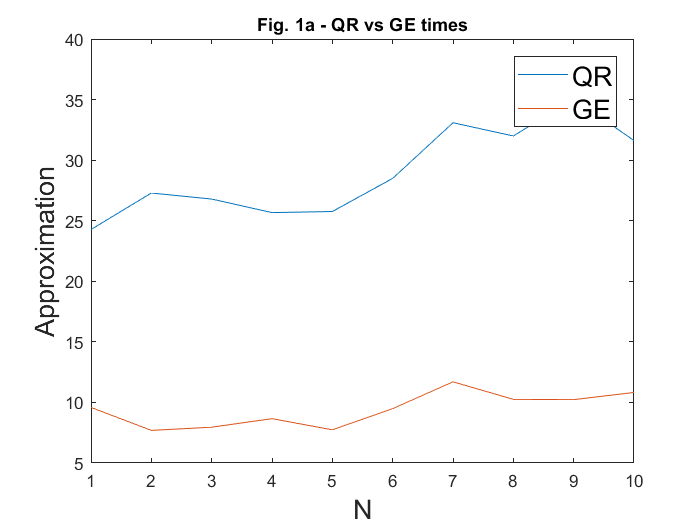


x_range = 1:trials;
plot(x_range, QR_times, x_range, GE_times)
title('Fig. 1a - QR vs GE times');
legend({'QR', 'GE'},'fontsize',16,'Location','northeast');
xlabel('N','fontsize',16);
ylabel('Seconds','fontsize',16);

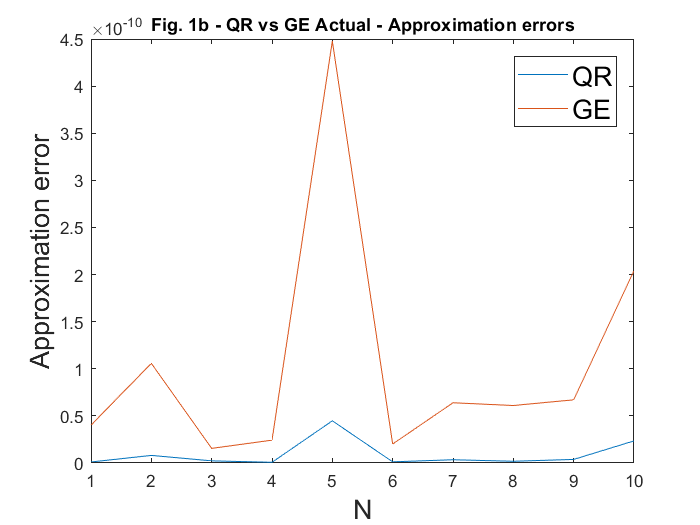


figure;plot(x_range, QR_errors, x_range, GE_errors)
title('Fig. 1b - QR vs GE Actual - Approximation errors');
legend({'QR', 'GE'},'fontsize',16,'Location','northeast');
xlabel('N','fontsize',16);
ylabel('Approximation error','fontsize',16);